**Exemplar trajectories**

rng('default');%initialize RNG for reproducibility

%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
% otherwise based on experimental data rates

motorState.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorState.pi0 =10*motorState.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorState.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration 
% derived from Stu data)
%processivity is synthesis limited
motorState.kOff0 = 100*motorState.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)
%increasing kOff from 10x to 100x eps0 makes pausing concentration
%dependent. Interesting
motorState.Fdetach = 1;%detachment force pN nm
motorState.Fstall = 100; %stall force pN nM
motorState.vF=40;%forward velocity nm/s
motorState.vB=0.1;%backward velocity nm/s

motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;
simPar.doFixedTime=true;
simPar.simTime = 2000;

**Nmax=1**

%Nmax = 1 each side (max number of motors), low concentration, which should give frequent pausing model
motorState.Nmax = 1;


**Low concentration**

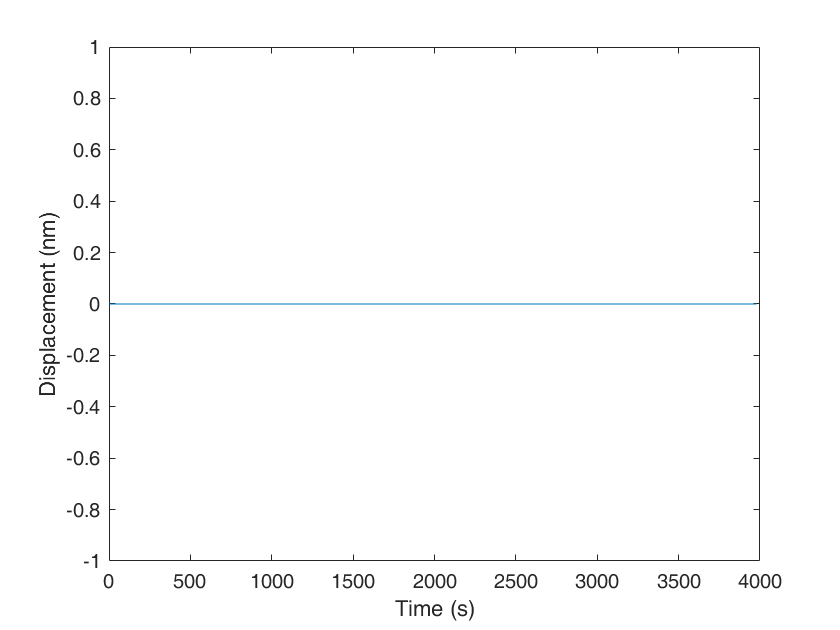

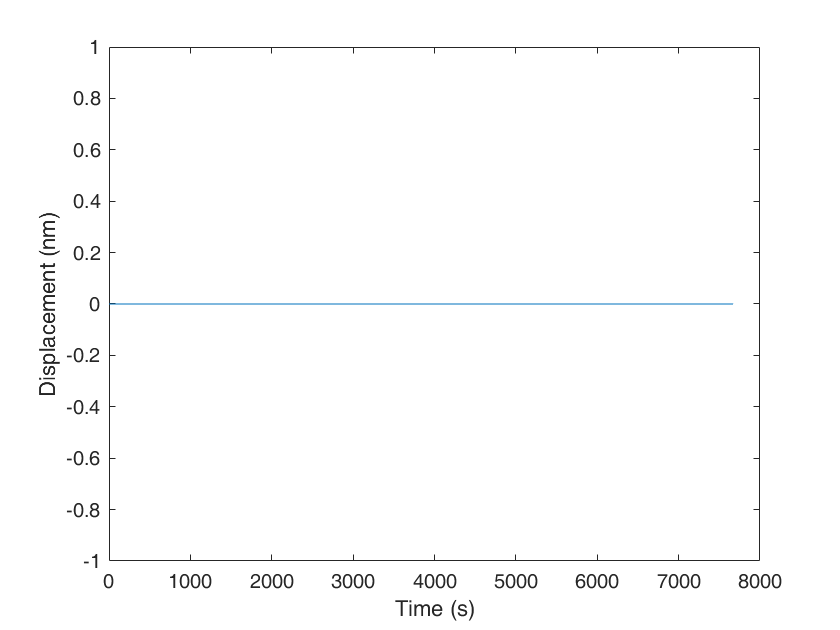

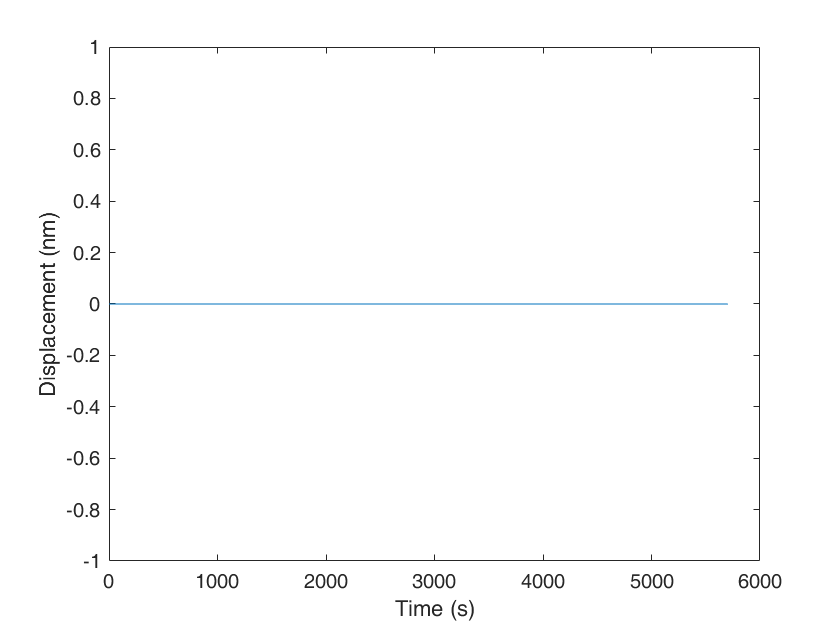

motorState.motorConcentration =1e-2;%arb units, essentiall scaling of low synthase concentration data here

for ii=1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    dynamics1Low{ii}=dynamics;
    motorTot= dynamics.Nminus+dynamics.Nplus;
    figure;
%     yyaxis left;
    plot(t,x);
    ylabel('Displacement (nm)');
%     yyaxis right % not showing it this way because the overlay looks
%     fuggly
%     stairs(t,motorTot);
%     ylabel('No. of bound synthases')
    xlabel('Time (s)');
    
end

**Intermediate concentration**

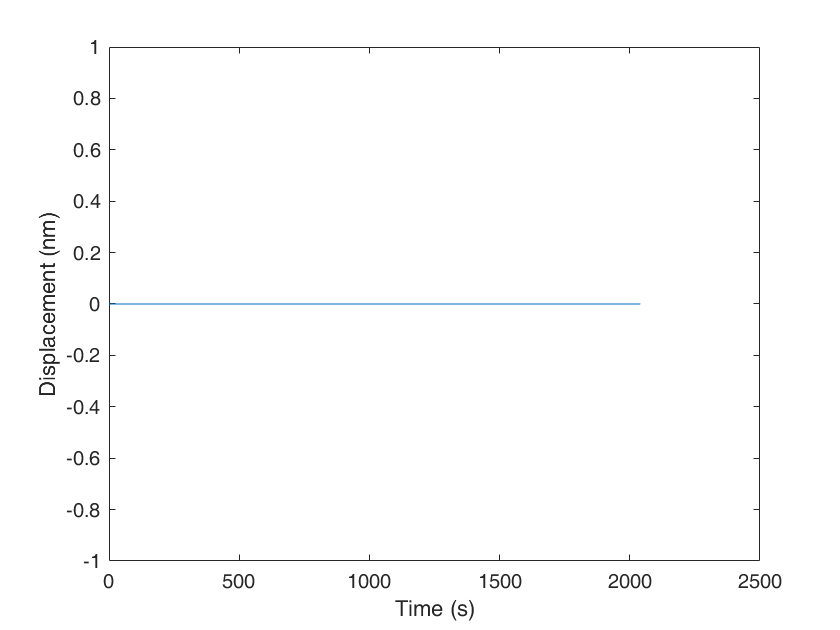

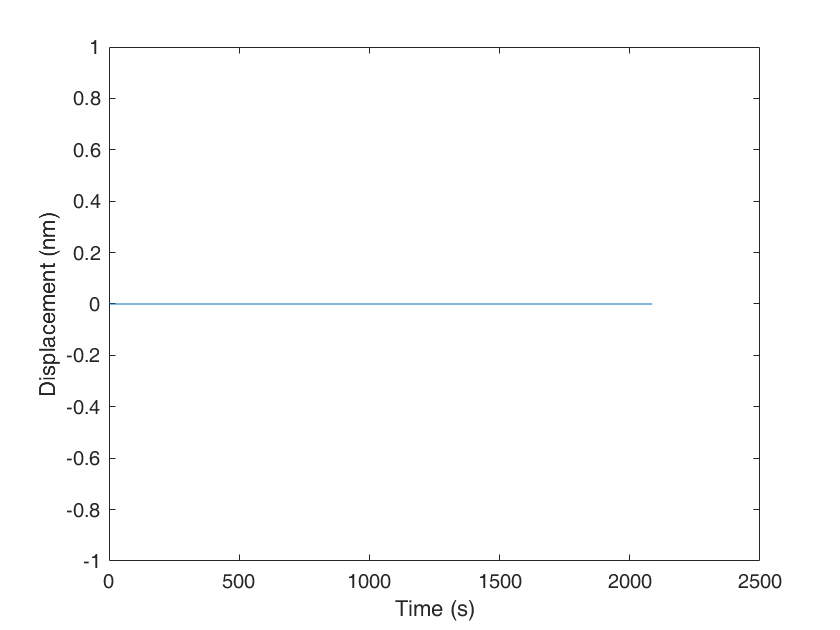

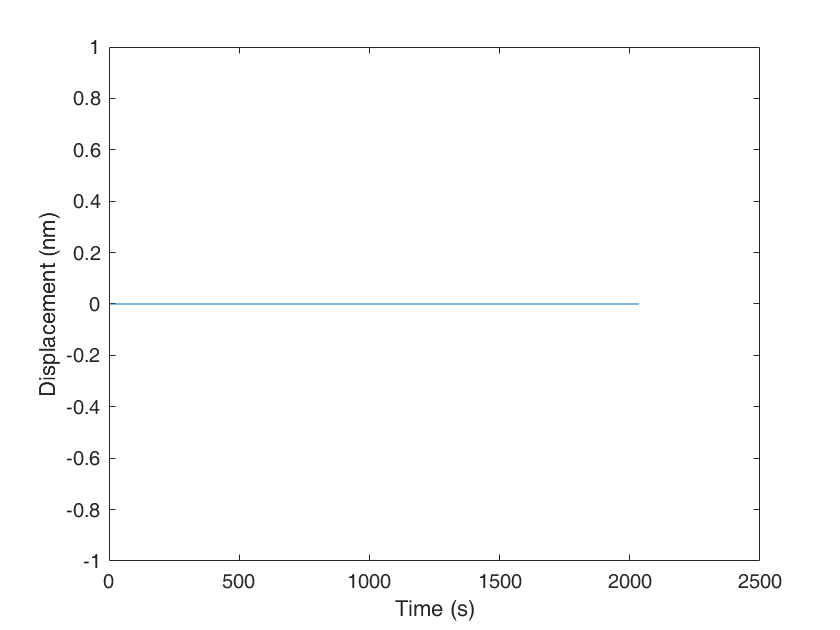

motorState.motorConcentration =1e0;%arb units, essentiall scaling of low synthase concentration data here

for ii = 1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    
    dynamics1Mid{ii}=dynamics;
    motorTot= dynamics.Nminus+dynamics.Nplus;
    figure;
%     yyaxis left;
    plot(t,x);
    ylabel('Displacement (nm)');
%     yyaxis right
%     stairs(t,motorTot);
%     ylabel('No. of bound synthases')
    xlabel('Time (s)');
end

**High concentration**

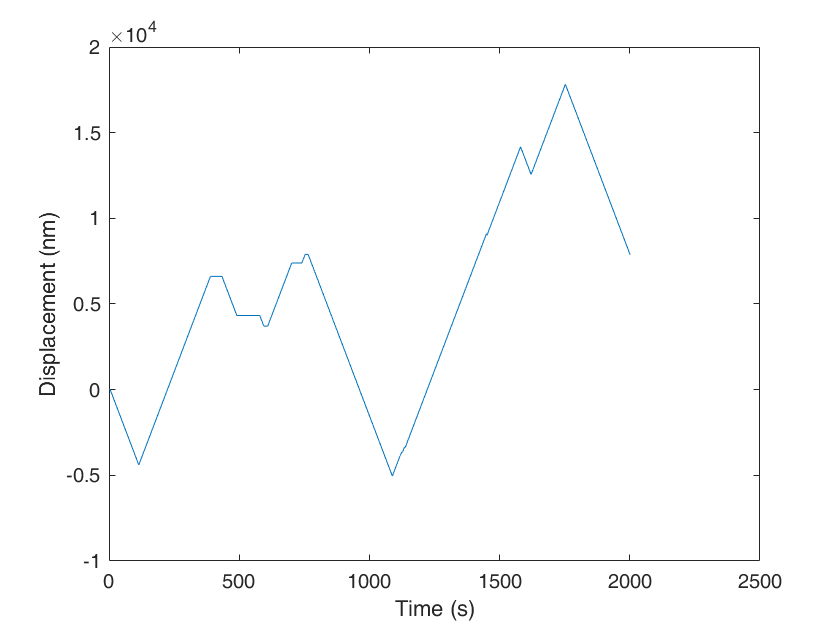

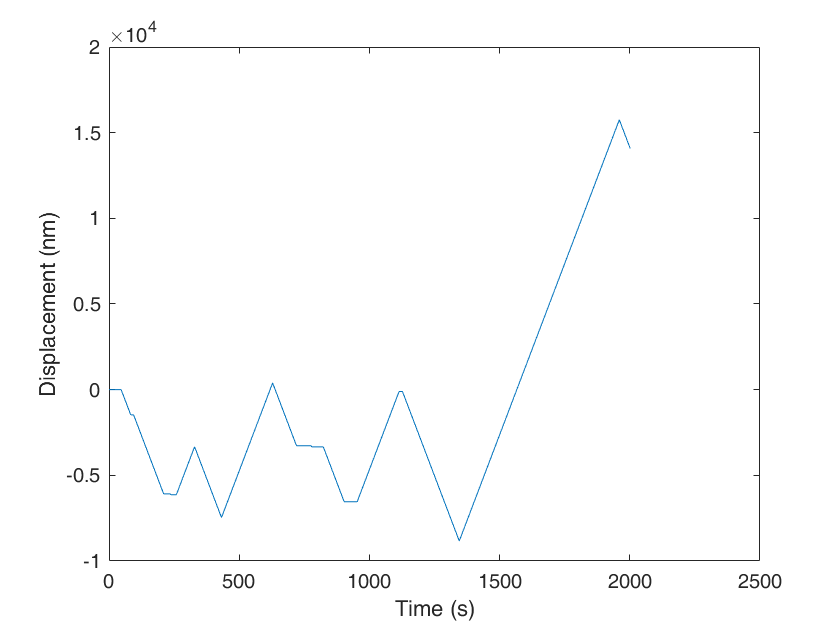

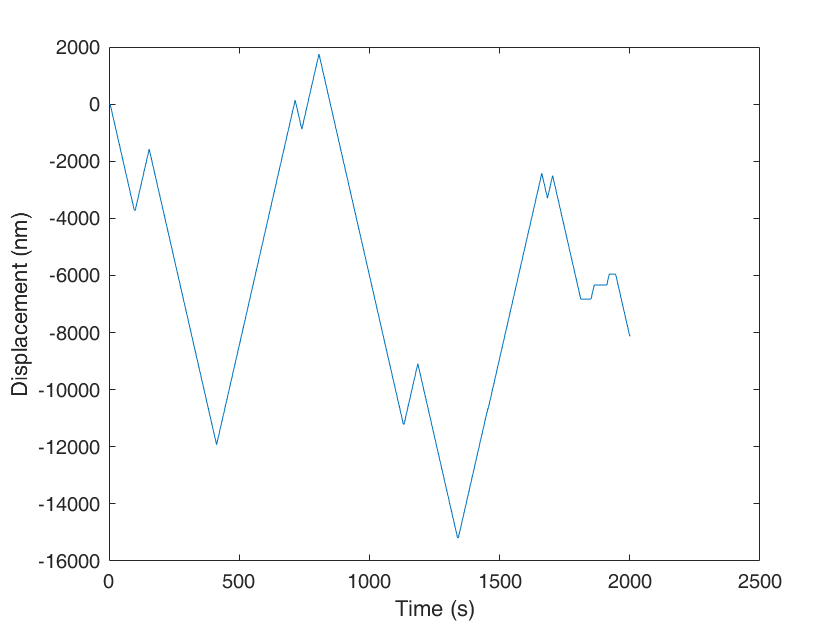

motorState.motorConcentration =1e2;%arb units, essentiall scaling of low synthase concentration data here

for ii =1:3
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    figure;
    plot(t,x);
    ylabel('Displacement (nm)');
    xlabel('Time (s)');
    dynamics1High{ii}=dynamics;
end

**Max motor = 1**

motorConcRange = 10.^(0:4).*0.01

motorConcRange =     0.0100    0.1000    1.0000   10.0000  100.0000



analysisPar.frameInterval = 6;
analysisPar.zeroSpeedThresh = 5;
analysisPar.switchTooCloseThresh = 4;
nSimRepeat=100

nSimRepeat = 100

motorState.Nmax = 1;

for ii = 1:numel(motorConcRange)
    motorState.motorConcentration =motorConcRange(ii);
    [processivityNmax1{ii}, speedNmax1{ii}, lifetimeNmax1{ii}, rateNmax1{ii}, fractionMotileNmax1(ii,:), simResultNmax1{ii},NmotorNmax1{ii}] =...
     quantifySimDynamics(motorState, simPar,analysisPar,nSimRepeat);
   lifetimeAllNmax1{ii} = lifetimeNmax1{ii}.All;
   lifetimeProcessiveNmax1{ii} = lifetimeNmax1{ii}.Processive;
   lifetimeStaticNmax1{ii} = lifetimeNmax1{ii}.Static;
end

%make the plots
fieldName={'c1','c2','c3','c4','c5'};
%categoryName={'10^-2', '10^-1','10^0','10^1','10^2'};
categoryName={'10^0', '10^1','10^2','10^3','10^4'};

save('220315 tug of war koff 100.mat');

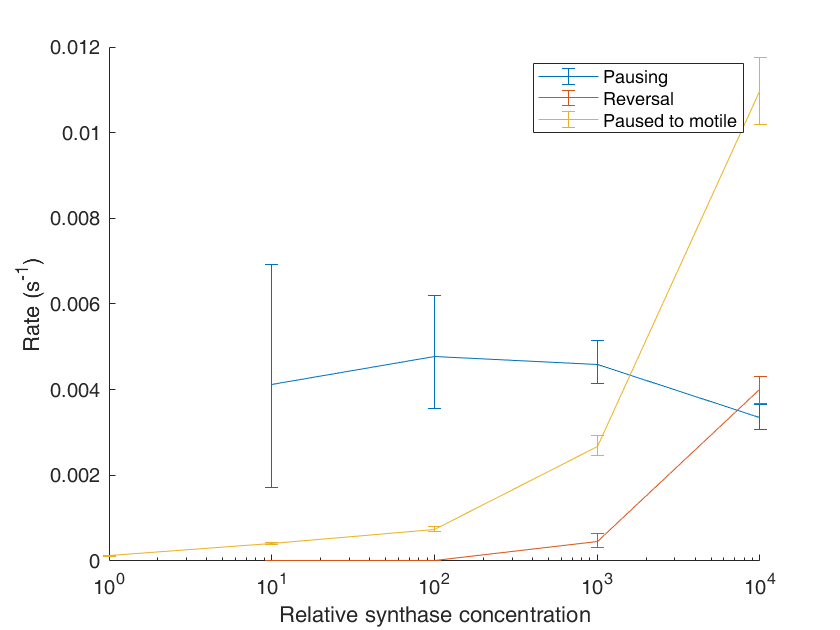

%rates
for ii = 1:numel(motorConcRange)
    pause_processive(ii,:) = rateNmax1{ii}.pause_processive;
    reversal_processive(ii,:) = rateNmax1{ii}.reversal_processive;
    staticToMotile(ii,:) = rateNmax1{ii}.staticToMotile;
end

figure;
hold all;
errorbar(motorConcRange*1e2, pause_processive(:,1),...
    pause_processive(:,1)-pause_processive(:,2),pause_processive(:,3)-pause_processive(:,1));
errorbar(motorConcRange*1e2, reversal_processive(:,1),...
    reversal_processive(:,1)-reversal_processive(:,2),reversal_processive(:,3)-reversal_processive(:,1));
errorbar(motorConcRange*1e2, staticToMotile(:,1),...
    staticToMotile(:,1)-staticToMotile(:,2),staticToMotile(:,3)-staticToMotile(:,1));
hA=gca;
hA.XScale='log';
legend('Pausing','Reversal','Paused to motile');
xlabel('Relative synthase concentration');
ylabel('Rate (s^{-1})')

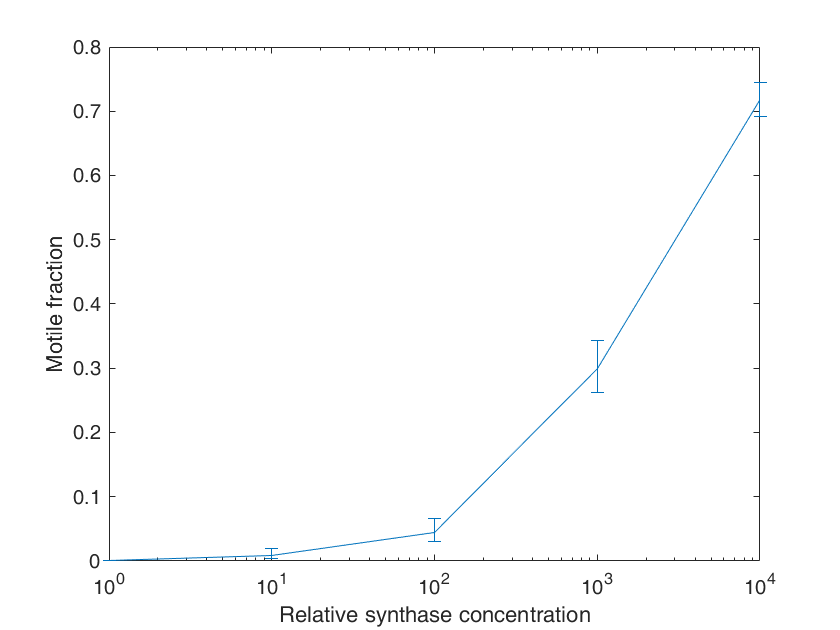

%faction motile v static
figure;
errorbar(motorConcRange*1e2, fractionMotileNmax1(:,1),...
    fractionMotileNmax1(:,1)-fractionMotileNmax1(:,2),fractionMotileNmax1(:,3)-fractionMotileNmax1(:,1));
hA=gca;
hA.XScale='log';
xlabel('Relative synthase concentration');
ylabel('Motile fraction') 